Scientific Programming - TCGA Ovarian Cancer dataset

01 - Import and clean the dataset

clear;
clc;
close all;

if ~exist("figures", "dir")
    mkdir("figures");
end

Import clinical files and gene expression data

clinical_patient = readtable( ...
    "data/data_clinical_patient.txt", ...
    "FileType","text", ...
    "Delimiter","\t", ...
    "CommentStyle","#");

clinical_sample = readtable( ...
    "data/data_clinical_sample.txt", ...
    "FileType","text", ...
    "Delimiter","\t", ...
    "CommentStyle","#");

expression_data = readtable( ...
    "data/data_mRNA_unified.txt", ...
    "FileType","text", ...
    "Delimiter","\t");

**Note: Gene-expression preprocessing**

The unified TCGA mRNA expression profile was used. The individual platforms were normalized separately: the Affymetrix platforms were processed using RMA, while the Agilent platform used LOWESS normalization followed by log2 transformation. The platform-specific expression values were then standardized across patients and integrated across the three platforms using factor analysis, after which the unified estimates were rescaled using gene-specific variability estimates.

Batch effects were detected in the individual platforms but were substantially reduced in the unified dataset. The authors checked this using permutation-based batch testing, PCA and hierarchical clustering, and chose not to apply further batch correction because empirical-Bayes adjustment produced only modest changes and could remove genuine biological differences between batches. 

Source: [https://doi.org/10.1038/nature10166](https://doi.org/10.1038/nature10166) (Supplementary Information)

Inspect the datasets: variable names, number of rows and columns.

size(clinical_patient) %491 x 7

ans =    491     7


size(clinical_sample) %488 x 15

ans =    488    15


size(expression_data) %11838 x 497

ans =        11838         497



clinical_patient.Properties.VariableNames

ans = 1×7 cell array
    {'PATIENT_ID'}    {'PRIMARY_THERAPY_OUTCOME_SUCCESS'}    {'PLATINUM_STATUS'}    {'OS_STATUS'}    {'OS_MONTHS'}    {'DFS_STATUS'}    {'DFS_MONTHS'}


clinical_sample.Properties.VariableNames

ans = 1×15 cell array
    {'SAMPLE_ID'}    {'PATIENT_ID'}    {'TUMOR_STAGE_2009'}    {'GRADE'}    {'TUMOR_RESIDUAL_DISEASE'}    {'ACGH_DATA'}    {'MRNA_DATA'}    {'SEQUENCED'}    {'COMPLETE_DATA'}    {'CANCER_TYPE'}    {'CANCER_TYPE_DETAILED'}    {'ONCOTREE_CODE'}    {'SAMPLE_TYPE'}    {'SOMATIC_STATUS'}    {'TMB_NONSYNONYMOUS'}


expression_data.Properties.VariableNames(1:5)

ans = 1×5 cell array
    {'Entrez_Gene_Id'}    {'TCGA_01_0630_01_11'}    {'TCGA_01_0631_01_11'}    {'TCGA_01_0633_01_11'}    {'TCGA_01_0636_01_11'}


Inspect the first rows: get patient ID format, sample ID format, how to match the samples from different files

head(clinical_patient)

       PATIENT_ID       PRIMARY_THERAPY_OUTCOME_SUCCESS    PLATINUM_STATUS     OS_STATUS      OS_MONTHS       DFS_STATUS        DFS_MONTHS
    ________________    _______________________________    _______________    ____________    _________    _________________    __________

    {'TCGA-61-1895'}         {'Stable Disease'   }          {'Tooearly'}      {'0:LIVING'}      1.41       {'0:DiseaseFree'}       1.41   
    {'TCGA-13-1510'}         {0×0 char           }          {'Tooearly'}      {'0:LIVING'}      2.56       {'0:DiseaseFree'}       2.56   
    {'TCGA-23-1809'}         {0×0 char           }          {'Tooearly'}      {'0:LIVING'}      0.53       {'0:DiseaseFree'}       0.53   
    {'TCGA-20-1687'}         {'Complete Response'}          {'Tooe

head(clinical_sample)

         SAMPLE_ID            PATIENT_ID       TUMOR_STAGE_2009    GRADE       TUMOR_RESIDUAL_DISEASE      ACGH_DATA    MRNA_DATA    SEQUENCED    COMPLETE_DATA       CANCER_TYPE                CANCER_TYPE_DETAILED            ONCOTREE_CODE    SAMPLE_TYPE    SOMATIC_STATUS    TMB_NONSYNONYMOUS
    ___________________    ________________    ________________    ______    __________________________    _________    _________    _________    _____________    __________________    ____________________________________    _____________    

expression_data(1:5,1:6)

ans = 5×6 table
    Entrez_Gene_Id    TCGA_01_0630_01_11    TCGA_01_0631_01_11    TCGA_01_0633_01_11    TCGA_01_0636_01_11    TCGA_01_0637_01_11
    ______________    __________________    __________________    __________________    __________________    __________________

           2               0.99675                1.1713                 1.9008               0.32021               0.96077     
           9               0.74366               0.91641                0.55753               0.65085               0.76543     
          10               0.10697               0.30388               0.082338               0.41721             -0.075023     
          12                0.7266                4.3839                 3.0339              -0.67054                5.9939     
     


% Patient ID column
clinical_patient.PATIENT_ID(1:5)

ans = 5×1 cell array
    {'TCGA-61-1895'}
    {'TCGA-13-1510'}
    {'TCGA-23-1809'}
    {'TCGA-20-1687'}
    {'TCGA-13-1404'}



clinical_sample.PATIENT_ID(1:5)

ans = 5×1 cell array
    {'TCGA-13-1510'}
    {'TCGA-23-1809'}
    {'TCGA-20-1687'}
    {'TCGA-13-1404'}
    {'TCGA-13-1506'}



clinical_sample.SAMPLE_ID(1:5)

ans = 5×1 cell array
    {'TCGA-13-1510-01'}
    {'TCGA-23-1809-01'}
    {'TCGA-20-1687-01'}
    {'TCGA-13-1404-01'}
    {'TCGA-13-1506-01'}


Inspect if there are unique IDs and how much overlap there is.

% Uniqueness of patient IDs
numel(unique(clinical_patient.PATIENT_ID))

ans = 491

height(clinical_patient)

ans = 491


% Uniqueness of sample IDs
numel(unique(clinical_sample.SAMPLE_ID))

ans = 488

height(clinical_sample)

ans = 488


% Uniqueness of patient IDs in sample table
numel(unique(clinical_sample.PATIENT_ID))

ans = 488

height(clinical_sample)

ans = 488


%no repeated patient IDs or sample IDs in any of the files

%check which patients dont have matching sample
patientOnly = setdiff( ...
    clinical_patient.PATIENT_ID, ...
    clinical_sample.PATIENT_ID);

patientOnly

patientOnly = 3×1 cell array
    {'TCGA-25-2390'}
    {'TCGA-29-2435'}
    {'TCGA-61-1895'}



%3 patients do not have corresponding sample IDs

There are in total 3 patients that don't have a corresponding sample ID, so they are excluded from further analysis

clinical_patient = clinical_patient( ...
    ismember(clinical_patient.PATIENT_ID, clinical_sample.PATIENT_ID), ...
    :);

% Keeps only patients with a corresponding sample-level record

%check size now
size(clinical_patient) %488 x 7

ans =    488     7


From 491 samples it decreased to 488 samples, this confirms that the 3 patients that were unmatched were removed from the dataset.

Match and merge the patient datasets by patient_ID

clinical_merged = innerjoin( ...
    clinical_sample, ...
    clinical_patient, ...
    "Keys","PATIENT_ID");

% Check dimensions
size(clinical_merged) %488 x 21

ans =    488    21


Match clinical samples to gene expression samples (sample_ID)

expressionSampleIDs = string( ...
    expression_data.Properties.VariableNames(2:end));

% Convert underscores to TCGA barcode format
expressionSampleIDs = strrep(expressionSampleIDs, "_", "-");

% Shorten barcode: TCGA-01-0630-01-11 -> TCGA-01-0630-01
expressionSampleIDs_short = extractBefore(expressionSampleIDs, 16);

% Check that shortening did not create duplicate IDs
numel(unique(expressionSampleIDs_short))

ans = 496

numel(expressionSampleIDs_short)

ans = 496


clinicalSampleIDs = string(clinical_merged.SAMPLE_ID);

% Match clinical samples to expression samples
[isMatched, expressionOrder] = ...
    ismember(clinicalSampleIDs, expressionSampleIDs_short);

sum(isMatched)

ans = 488


% Check unmatched samples
clinicalSampleIDs(~isMatched)


ans = 

  0×1 empty string array




% Extract expression values
expressionValues = expression_data{:,2:end};

% Reorder expression columns so they match clinical_merged
expressionValues_matched = ...
    expressionValues(:, expressionOrder);

% Store gene IDs
geneIDs = expression_data.Entrez_Gene_Id;

% Check result
size(expressionValues_matched)

ans =        11838         488


Check for missingness and outcome availability

% Check missing values in all clinical variables

for i = 1:width(clinical_merged)
    variableName = clinical_merged.Properties.VariableNames{i};
    nMissing = sum(ismissing(clinical_merged.(variableName)));

    fprintf('%s: %d missing\n', variableName, nMissing);
end

SAMPLE_ID: 0 missing
PATIENT_ID: 0 missing
TUMOR_STAGE_2009: 0 missing
GRADE: 0 missing
TUMOR_RESIDUAL_DISEASE: 0 missing
ACGH_DATA: 0 missing
MRNA_DATA: 0 missing
SEQUENCED: 0 missing
COMPLETE_DATA: 0 missing
CANCER_TYPE: 0 missing
CANCER_TYPE_DETAILED: 0 missing
ONCOTREE_CODE: 0 missing
SAMPLE_TYPE: 0 missing
SOMATIC_STATUS: 0 missing
TMB_NONSYNONYMOUS: 172 missing
PRIMARY_THERAPY_OUTCOME_SUCCESS: 94 missing
PLATINUM_STATUS: 1 missing
OS_STATUS: 0 missing
OS_MONTHS: 1 missing
DFS_STATUS: 25 missing
DFS_MONTHS: 93 missing



% Inspect categorical values in important clinical variables

unique(clinical_merged.TUMOR_STAGE_2009)

ans = 8×1 cell array
    {'IIA' }
    {'IIB' }
    {'IIC' }
    {'IIIA'}
    {'IIIB'}
    {'IIIC'}
    {'IV'  }
    {'NA'  }


unique(clinical_merged.GRADE)

ans = 3×1 cell array
    {'G2'}
    {'G3'}
    {'NA'}


unique(clinical_merged.TUMOR_RESIDUAL_DISEASE)

ans = 5×1 cell array
    {'1-10 mm'               }
    {'11-20 mm'              }
    {'>20mm'                 }
    {'NA'                    }
    {'No Macroscopic disease'}


unique(clinical_merged.PRIMARY_THERAPY_OUTCOME_SUCCESS)

ans = 5×1 cell array
    {0×0 char             }
    {'Complete Response'  }
    {'Partial Response'   }
    {'Progressive Disease'}
    {'Stable Disease'     }


unique(clinical_merged.PLATINUM_STATUS)

ans = 5×1 cell array
    {0×0 char   }
    {'Missing'  }
    {'Resistant'}
    {'Sensitive'}
    {'Tooearly' }


unique(clinical_merged.DFS_STATUS)

ans = 3×1 cell array
    {0×0 char               }
    {'0:DiseaseFree'        }
    {'1:Recurred/Progressed'}


unique(clinical_merged.OS_STATUS)

ans = 2×1 cell array
    {'0:LIVING'  }
    {'1:DECEASED'}



tabulate(clinical_merged.TUMOR_STAGE_2009)

  Value    Count   Percent
   IIIC      353     72.34%
   IIIB       20      4.10%
     NA        5      1.02%
     IV       79     16.19%
    IIC       17      3.48%
   IIIA        7      1.43%
    IIB        4      0.82%
    IIA        3      0.61%


tabulate(clinical_merged.GRADE)

  Value    Count   Percent
     G3      419     85.86%
     G2       57     11.68%
     NA       12      2.46%


tabulate(clinical_merged.TUMOR_RESIDUAL_DISEASE)

                   Value    Count   Percent
                 1-10 mm      223     45.70%
  No Macroscopic disease       89     18.24%
                      NA       57     11.68%
                   >20mm       89     18.24%
                11-20 mm       30      6.15%


tabulate(clinical_merged.PRIMARY_THERAPY_OUTCOME_SUCCESS)

                Value    Count   Percent
    Complete Response      276     70.05%
  Progressive Disease       37      9.39%
       Stable Disease       24      6.09%
     Partial Response       57     14.47%


tabulate(clinical_merged.PLATINUM_STATUS)

      Value    Count   Percent
  Sensitive      197     40.45%
    Missing      143     29.36%
  Resistant       90     18.48%
   Tooearly       57     11.70%


tabulate(clinical_merged.DFS_STATUS)

                  Value    Count   Percent
  1:Recurred/Progressed      349     75.38%
          0:DiseaseFree      114     24.62%


Check missingness for DFS feature

dfsStatusAvailable = ~ismissing(clinical_merged.DFS_STATUS);
dfsTimeAvailable   = ~ismissing(clinical_merged.DFS_MONTHS);

% Both status and time available
sum(dfsStatusAvailable & dfsTimeAvailable)

ans = 395


% Status available but time missing
sum(dfsStatusAvailable & ~dfsTimeAvailable)

ans = 68


% Time available but status missing
sum(~dfsStatusAvailable & dfsTimeAvailable)

ans = 0


% Both missing
sum(~dfsStatusAvailable & ~dfsTimeAvailable)

ans = 25

Since DFS is one of the features I want to look at the most, I will only keep the samples that have both time and status available (395 samples). 

%DFS analysis cohort

dfsAvailable = ...
    ~ismissing(clinical_merged.DFS_STATUS) & ...
    ~ismissing(clinical_merged.DFS_MONTHS);

clinical_dfs = clinical_merged(dfsAvailable, :);
expression_dfs = expressionValues_matched(:, dfsAvailable);

size(clinical_dfs)

ans =    395    21


size(expression_dfs)

ans =        11838         395


Create event variable for DFS status

dfsEvent = strcmp(clinical_dfs.DFS_STATUS, ...
                  '1:Recurred/Progressed');

sum(dfsEvent)      % 283 events

ans = 283

sum(~dfsEvent)     % 112 censored

ans = 112

Visualization of missing data

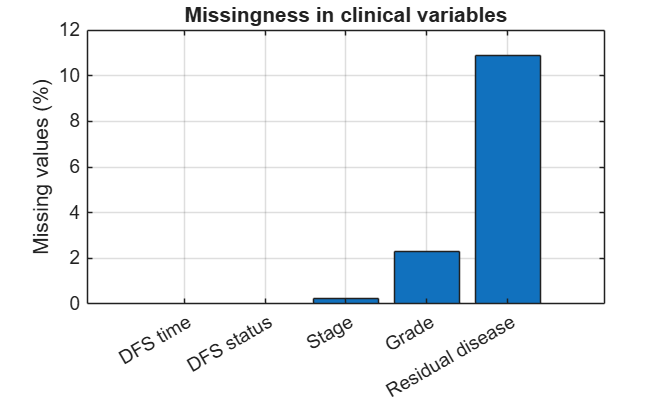

%% Clinical missingness overview

% Variables used later in the survival analysis
stageStr = string(clinical_dfs.TUMOR_STAGE_2009);
gradeStr = string(clinical_dfs.GRADE);
residualStr = string(clinical_dfs.TUMOR_RESIDUAL_DISEASE);

% Count both true missing values and text encoded as "NA"
missingStage = ...
    sum(ismissing(stageStr) | stageStr == "NA");

missingGrade = ...
    sum(ismissing(gradeStr) | gradeStr == "NA");

missingResidual = ...
    sum(ismissing(residualStr) | residualStr == "NA");

missingDFS_Time = ...
    sum(isnan(clinical_dfs.DFS_MONTHS));

missingDFS_Status = ...
    sum(ismissing(string(clinical_dfs.DFS_STATUS)));

features = { ...
    'DFS time', ...
    'DFS status', ...
    'Stage', ...
    'Grade', ...
    'Residual disease'};

missingCounts = [ ...
    missingDFS_Time, ...
    missingDFS_Status, ...
    missingStage, ...
    missingGrade, ...
    missingResidual];

missingPercent = ...
    100 * missingCounts / height(clinical_dfs);

%% Visualize missing clinical data

figure;

bar(missingPercent)

xticklabels(features)
xtickangle(30)

ylabel('Missing values (%)')
title('Missingness in clinical variables')

grid on

saveas(gcf, "figures/missingness_clinical.png");


missingTable = table( ...
    features', ...
    missingCounts', ...
    missingPercent', ...
    'VariableNames', ...
    {'Variable','MissingCount','MissingPercent'});

disp(missingTable)

          Variable          MissingCount    MissingPercent
    ____________________    ____________    ______________

    {'DFS time'        }          0                  0    
    {'DFS status'      }          0                  0    
    {'Stage'           }          1            0.25316    
    {'Grade'           }          9             2.2785    
    {'Residual disease'}         43             10.886    



Save data 

save("results/cleaned_data.mat", ...
    "clinical_merged", ...
    "clinical_dfs", ...
    "expressionValues_matched", ...
    "expression_dfs", ...
    "expression_data", ...
    "geneIDs", ...
    "dfsEvent");